# Analisis dinámico del aerotaxi

clear; clc

% Especificaciones "del orden" del City Airbus: 

% masa
m = 2000;       % kg
g = 9.8;        % m/s²
Fg = m*g;       % peso en N

% Inercia de caja 4.0 x 2 x 1.5 m3
x = 4.0; y = 2.0; z = 1.5;
% En realidad nuestro dron ocupa una caja de 25x25x4.5 cms
Ix = 1/12 * m * (y^2 + z^2)

Ix = 1.0417e+03

Iy = 1/12 * m * (x^2 + z^2)

Iy = 3.0417e+03

Iz = 1/12 * m * (x^2 + y^2)

Iz = 3.3333e+03

## Fuerza de sustentación

En esta ocasión, los rotores son asimétricos con respecto al eje Y.


dN = 1;     % distancia del tren delantero al CM
dS = 2.5;   % distancia del tren trasero al CM
h  = 0.5;    % altura de los rotores respecto del CM

% Fuerzas de los rotores
syms fNW fNE fSW fSE

% Definir las ecuaciones
eqs = [  fNW + fNE + fSW + fSE == m * g
                (fNW + fNE)*dN == (fSW + fSE)*dS
                           fNW == fNE
                           fSW == fSE               ];

% Resolver el sistema
sol = solve(eqs, [fNW fNE fSW fSE]);

FT_N_hov = eval(sol.fNE);
FT_S_hov = eval(sol.fSE);


## Fuerza de empuje aerodinámico

Según bibliografía, el rotor de un helicóptero de tamaño medio (1400kgm) gira a 300 RPM en sustentación. 

Nosotros asumiremos para nuestro cuadricóptero que se sustenta con los 4 rotores a 400 RPM (las aspas son mucho más pequeñas por lo que generan menos empuje).

Calculamos $\textrm{FT}=\textrm{kFT}*w^2$

% lo ajustamos con la expresión FT = kFT * w²
w_hov = convangvel(400,'rpm','rad/s')

w_hov = 41.8879

kFT_N = FT_N_hov / w_hov^2  

kFT_N = 3.9895

kFT_S = FT_S_hov / w_hov^2  

kFT_S = 1.5958

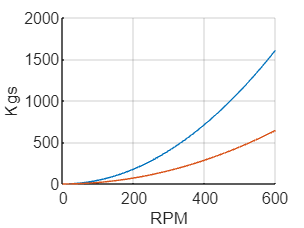


clf
grid on
hold on
xlabel('RPM')
ylabel('Kgs')

rpm = 0:10:600;
radps = convangvel(rpm,'rpm','rad/s');
FT_N = kFT_N * radps.^2;
FT_S = kFT_S * radps.^2;
plot(rpm, FT_N/g)
plot(rpm, FT_S/g)



% Asumimos velocidad maxima del motor
w_max = convangvel(600,'rpm','rad/s') 

w_max = 62.8319

% y obtenemos  
P_N_max = kFT_N * w_max.^2 /g   % peso máximo soportado por cada rotor delantero

P_N_max = 1.6071e+03

P_S_max = kFT_S * w_max.^2 /g   % peso máximo soportado por cada rotor trasero

P_S_max = 642.8571

P_max = 2*P_N_max + 2*P_S_max   % peso máximo del aparato

P_max = 4500

## Momento de arrastre de los rotores

Momento que experimenta el rotor en sentido contrario a su velocidad de giro:

MDR = kMDR * w². 

Asumimos que:

- No hay rozamiento con el aire 

- El dron está estabilizado

- Si solo contamos con el arrastre de un motor delantero, el dron tarda 2 segundos en alcanzar una velocidad de 1 vuelta por segundo

- Si solo contamos con el arrastre de un motor trasero, el dron tarda 8 segundos en alcanzar una velocidad de 1 vuelta por segundo

% tren delantero
acel_ang = 2*pi / 2;      % aceleración angular necesaria
MDR = Iz * acel_ang;      % momento angular necesario
kMDR_N = MDR / w_hov^2   

kMDR_N = 5.9683


% tren trasero
acel_ang = 2*pi / 8;      % aceleración angular necesaria
MDR = Iz * acel_ang;      % momento angular necesario
kMDR_S = MDR / w_hov^2   

kMDR_S = 1.4921

## Fuerza de arrastre aerodinamico

Fuerza de rozamiento con el aire, contraria a la velocidad.

      FD = -kFD * r_dot*|r_dot|  

Depende de la forma del objeto en cada eje.

Asumiremos que la aeronave se desplaza horizontalmente a 120 Kms por hora con una inclinación de 10º

% Fuerza de sustentación es igual al peso
% La fuerza de arrastre es

pitch = 10;
FD = Fg * tand(pitch);

% Descompongo en ejes

% OTRA OPCION
% 
% Teniendo en cuenta la velocidad máxima de descenso
%   humano cae a 55m/s
%   gota   cae a 10m/s
% Asumimos
%   drone  cae a 100m/s de morro
kFDx = Fg / 100^2

kFDx = 1.9600

%   drone  cae a 90m/s de costado
kFDy = Fg / 90^2

kFDy = 2.4198

%   drone  cae a 80m/s de panza
kFDz = Fg / 60^2

kFDz = 5.4444



% Eje vertical:
VzDOWN_max = 40;
% en consecuencia, cuando vuela a velocidad máxima de ascenso, los motores actuan a
kFDz = Fg / VzDOWN_max^2           % 36e-04 --------------------------

kFDz = 12.2500

% DJI establece la velocidad máxima vertical en 6m/s
% nosotros deberemos acotar tambien

% En definitiva
kFD  = [kFDx  0    0  ;
          0  kFDy  0  ; 
          0    0  kFDz ];

## Momento de arrastre aerodinamico

Momento de rozamiento con el aire que sufre el drone al girar. Es contrario a la velocidad angular. 

MD = -kMD * rpy_dot * `rpy_dot` depende de la forma del objeto en cada eje.

% Ejes horizontales:
% Asumimos 
%   rozamiento similar en ambos ejes (aunque el fuselaje no sea igual)
%   escenario sin gravedad
%   los motores actuan a velocidad de sustentación
%   pero los motores de un lado estan invertidos!!
%   el dron adquiere una velocidad angular terminal de 10 vueltas/s
%   cuando MD = MT
vel_ang_max = 10* 2*pi;  % rad/s
% operando
MDxy = Fg * L; % momento angular de los motores

Unrecognized function or variable 'L'.

kMDxy = MDxy / vel_ang_max^2 % 1.1077e-04

% Eje vertical:
% Asumimos 
%   escenario con gravedad
%   2 motores opuestos actuan a velocidad de sustentación
%   el dron adquiere una velocidad angular terminal de 2 vueltas/s
%   cuando MD = MT
vel_ang_max = 2 * 2*pi;  % rad/s
% operando
MDz  = MDR2;                % momento angular de los motores
kMDz = MDz / vel_ang_max^2 % = 7.8914e-05

% En definitiva
kMD  = [kMDxy   0     0  ;
          0   kMDxy   0  ; 
          0     0   kMDz ];

## Servosistema con realimentacion controlada de estado y salida

% load('linsys_x08y04_OLD.mat')
% Aold = linsys_x08y04.a;
% Bold = linsys_x08y04.b;
% Cold = linsys_x08y04.c;

load('linsys1.mat')
A = linsys1.a;
B = linsys1.b;
C = linsys1.c;



% disp('Autovalores de A:');
% disp(eig(A));
%  
% disp('Dimension de A:');
% disp(length(A));
% disp('Rango de matriz de controlabilidad:');
% disp(rank(ctrb(A,B)));


AA = [ A  zeros(8,4) ;
       C  zeros(4,4) ];
   
BB = [ B          ;
       zeros(4,4) ];
   
% disp('DimensiOn de AA:');
% disp(length(AA));
% disp('Rango de matriz de controlabilidad:');
% disp(rank(ctrb(AA,BB)));


%PP = [-6 -6 -7 -7 -8 -8 -8 -8 -9 -9 -9 -9]; % Drone Challenge version definitiva usada
% PP = [-1 -1 -2 -2 -3 -3 -3 -3 -4 -4 -4 -4]; % Drone Challenge 2023
PP = [-2 -2 -3 -3 -4 -4 -4 -4 -5 -5 -5 -5]; % Drone Challenge 2023
KK = place(AA,BB,PP);
Kx = KK(:,1:8)
Ki = KK(:,9:12)

## Ejemplos de iteración de control

Drone suspendido en el aire

% vector de estado
x0 =[ 0   % ePhi
      0   % eTheta
      0   % bWx
      0   % bWy
      0   % bWz
      0   % bXdot
      0   % bYdot
      0   % bZdot
];


% vector de salida
y = [ 0   % bXdot
      0   % bYdot
      0   % bZdot
      0   % bWz
];      

r = [ 0   % bXdot
      0   % bYdot
      0   % bZdot
      0   % hZdot
];

e = y - r

interval = 0;

E = [0 0 0 0]';
E = E + (e * interval);


% Wr = Hs - Kx * x - Ky * E

